Tmax = 0.02;

fk = [100 1500 2500];

Ak = [10 4 3];

tk= 0 : 0.00001 : Tmax;

Xk = Ak(1)*cos(2*pi*fk(1)*tk)-Ak(2)*cos(2*pi*fk(2)*tk)+Ak(3)*cos(2*pi*fk(3)*tk)

Xk =     9.0000    8.9806    8.9232    8.8301    8.7048    8.5524    8.3789    8.1917    7.9985    7.8081    7.6291    7.4707    7.3414    7.2497    7.2032    7.2086    7.2713    7.3956    7.5843    7.8383    8.1572    8.5386    8.9785    9.4711   10.0092   10.5840   11.1856   11.8028   12.4238   13.0362   13.6271   14.1839   14.6941   15.1458   15.5281   15.8312   16.0467   16.1675   16.1888   16.1073   15.9219   15.6335   15.2452   14.7619   14.1906   13.5402   12.8211   12.0451   11.2252   10.3755



Pk = Ak.*Ak/2;

Ptotal = sum(Pk);

Pperc = Pk/ Ptotal;

fmax = 1500;

fs = 2 * fmax; Ts = 1/fs;

td = 0 : Ts : Tmax;

Xd = Ak(1)*cos(2*pi*fk(1)*td)-Ak(2)*cos(2*pi*fk(2)*td);

subplot(2,1,1),plot(tk,Xk,'k');
title('Kontinualni signal');
xlabel('Vreme');

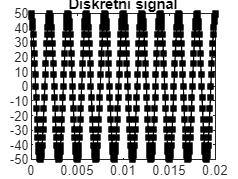


subplot(2,2,2),stem(0:length(td)-1,Xd);
title('Diskretni signal');
xlabel('Odbirci');